# Test Case - Motor Generator 1

mdl = "MotorGenerator1_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorGenerator1_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", Time="2");
simIn = setBlockParameter(simIn, mdl+"/Eng Trq Cmd", After="100");

simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", Before="10");
simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", Time="5");
simIn = setBlockParameter(simIn, mdl+"/MG1 Trq Cmd", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.engine_speed_rpm", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "20");

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

% The use of applyToModel below is optional.
% Comment out applyToModel to avoid updating the model file,
% and you can still run simulation.
applyToModel(simIn)

## Visualize Simulation Result

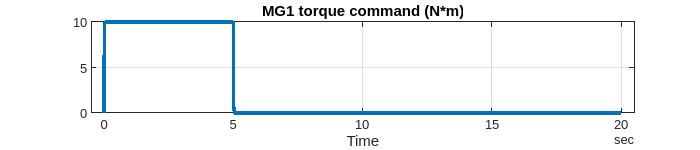

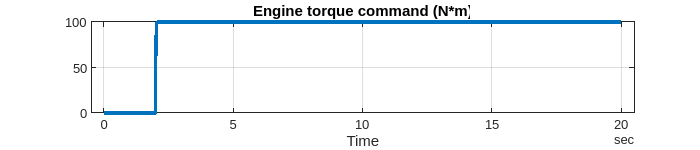

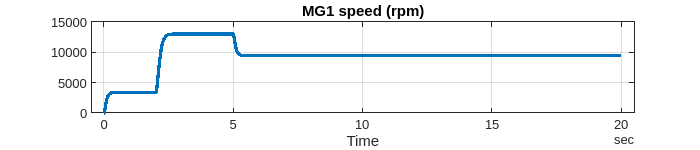

simData = extractTimetable(simOut.logsout);

sigNames = [ ...
  "MG1 torque command", ...
  "Engine torque command", ...
  "MG1 speed", ...
  "Engine speed", ...
  "MG1 torque", ...
  "Engine torque", ...
  "MG1 mechanical power", ...
  "MG1 power rate", ...
  "Engine power", ...
  "Battery power" ];

for i = 1 : numel(sigNames)
  fig = plotSimulationResultSignal(SimData = simData, SignalName = sigNames(i));
  fig.Position(4) = 150;
end

*Copyright 2021-2022 The Mathworks, Inc.*